x = 0.3460

y = 0

z = 0.1386

coord =     0.3460         0    0.1386


q1 = 0.5166

q2 = 1.0402

th2 = -0.5236

th1 = 0

th2 = -30.0000

th3 = 90

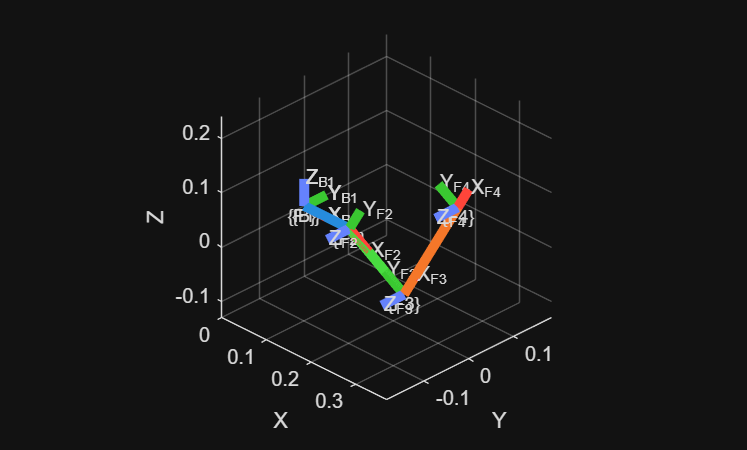

IndividualIK

function IndividualIK
L0 = 0.12256;
L1 = 0.1020;
L2 = 0.1420;
L3 = 0.2420;


%Individual calc on define th1, th2, th3
th1 = 0;
th2 = -30;
th3 = 90;

dh = [
    0, 0, 0, th1;
    L1, 90, 0, th2;
    L2, 0, 0, th3;
    L3, 0, 0, 0;
    ];

B = se3;

F1 = TfromDH(dh(1, :));
F2 = F1*TfromDH(dh(2, :));
F3 = F2*TfromDH(dh(3, :));
F4 = F3*TfromDH(dh(4, :));
H = F4.tform;

x = H(1,4)
y = H(2,4)
z = H(3,4)

%x=0.45;
%y=0.00;
%z=0.0766;
coord = [x,y,z]
[th1,th2,th3] = ik(x,y,z)
thetas = [th1,th2,th3];

frames = [B; F1; F2; F3; F4];
labels = {'B'; 'F1'; 'F2'; 'F3'; 'F4'};

figure;
for n = 1:size(frames, 1)

    plotTransforms(frames(n), 'FrameSize', 50e-3, 'FrameAxisLabels', 'on', 'FrameLabel', labels{n}, 'AxisLabels', 'on');
    hold on;

    if n < size(frames,1)
        draw_link(frames(n).trvec, frames(n+1).trvec);
    end

end

for l = findobj('Type', 'Line'), set(l, 'LineWidth', 5); end

view(45, 30);
end

function T = TfromDH(dh)

a = dh(1);
al = dh(2);
d = dh(3);
th = dh(4);

R = [cosd(th), -sind(th), 0; cosd(al)*sind(th), cosd(al)*cosd(th), -sind(al); sind(al)*sind(th), sind(al)*cosd(th), cosd(al)];
D = [a, -sind(al)*d, cosd(al)*d];

T = se3(R, D);

end

function draw_link(pos1, pos2)

line([pos1(1), pos2(1)], [pos1(2), pos2(2)], [pos1(3), pos2(3)]);

end

function [th1,th2,th3] = ik(x,y,z)

L_L0 = 0.12256;
L_L1 = 0.1020;
L_L2 = 0.1420;
L_L3 = 0.2420;
%CHECK ANGLES ARE WITHIN BOUNDS TBC

th1 = atan2(y,x);
% if x<0
%     th1 = atan(y/x);
% elseif x>=0
%     th1 = atan(-y/-x);
% end

%To determine if end effector is beneath L1
L1x = L_L1*cos(th1);
L1y = L_L1*sin(th1);
%START OF L2 IN XY
L1xy = sqrt(L1x^2+L1y^2);

%Origin to End effector
xy=sqrt(x^2+y^2);

%End of coxa to End effector on z plane x and y component
%xi=(O_E-L_L1)*cos(th1);
%yi=(O_E-L_L1)*sin(th1);

%End of coxa to end effector on z plane combined components
%C_E=sqrt(xi^2+yi^2) %DOESNT WORK CANT GO -VE XI
C_E=sqrt((L1x-x)^2+(L1y-y)^2);

%End of coxa to End effector in x/y/z plane
L=sqrt(C_E^2+z^2);

%TH2

if xy<L1xy
    q1= atan2(z,-C_E)
elseif xy>=L1xy
    q1= atan2(z,C_E)
end
q2 = acos((L_L2^2+L^2-L_L3^2)/(2*L_L2*L))

%Wierd fringe case of (45,0,0) or (-45,0,0) where q2 becomes imaginary
%(ONLY AT THESE EXACT THETAS
if isreal(q2)
    q2=q2;
else 
    q2=0;
end


% if abs(q1)>pi/2
%     if z>=0
%         th2=q1+q2;
%     elseif z<0
%         th2=q1+q2;
%     end
% elseif abs(q1)<=pi/2
%     if z<0
%         th2=q1+q2;
%     elseif z>=0
%         th2=q1+q2;
%     end
% end

if x<=L1x
    if z>0
        th2=q1-q2;
    elseif z<=0
        th2=q1+q2;
    end
elseif x>L1x
    if z>0
        th2=q1-q2;
    elseif z<=0
        th2=q1+q2;
    end
end
th2
%TH3
%Find the line of Th2 and determine if final point is above or below it

phi = acos((L_L2^2+L_L3^2-L^2)/(2*L_L2*L_L3));
L2z = L_L2*sin(th2);
L2x = cos(th1)*L_L2*cos(th2);
L2y = sin(th1)*L_L2*cos(th2);
L2xy= sqrt(L2x*L2x + L2y*L2y);

% if L1x>L2x
%     L2xy = -L2xy;
% end 
% Z-value on the line from J1 to J2 (TH2) at the point of x
zi = (L2z/(L2xy))*(x-L1x);

if z>zi
    th3 = pi-phi;
elseif z<zi
    th3 = phi-pi;
elseif z==zi
    th3 = 0.0;
end


% if L2z-z>0
%     th3 = phi-pi;
% elseif L2z-z<0
%     th3 = pi-phi;
% elseif L2z-z==0
%     if q1>0
%         th3=phi-pi;
%     elseif q1<0
%         th3=pi-phi;
%     elseif q1==0
%         th3 = 0;
%     end
% end

th1=th1*180/pi;
th2=th2*180/pi;
th3=th3*180/pi;


end